# Sort Connection Matrix Oh2014 by Structure

## Load Data

load("structureInfoTableOh.mat")
load("expEnergyMatrixOh_nonMissing.mat")
load("expEnergyMatrixOh_nonMissing_normalizzed.mat")
load("connectionMatrixOhP005.mat")
load("connectionIndexPairListOhP005.mat")

NStructureOh = 213;
NConnection = 3123;
NGene = 9111;

## Memo : Sort Target Data

% structureInfoTableOh
% expEnergyMatrixOh_nonMissing_normalizzed
% connectionMatrixOhP005
% connectionIndexPairListOhP005 (Remake)

## Load SupTable 1

oh2014Table1 = importdata('Oh2014SupTable1.xlsx');

%save("oh2014Table1.mat","oh2014Table1")

## Get Acronym  & Major Region Name List

% Acronym List
acronymListOhTbl1 = string(oh2014Table1.textdata.VoxelCount_295Structures(2:296,3));
majorRegionListOhTbl1 = string(oh2014Table1.textdata.VoxelCount_295Structures(2:296,5));
majorRegionNames = unique(majorRegionListOhTbl1)

majorRegionNames = 13×1 の string 配列
    "Cerebellar Cortex"
    "Cerebellar Nuclei"
    "Cortical Subplate"
    "Hippocampal Formation"
    "Hypothalamus"
    "Isocortex"
    "Medulla"
    "Midbrain"
    "Olfactory Areas"
    "Pallidum"
    "Pons"
    "Striatum"
    "Thalamus"


% make MR Name List same to Fulcher 2016
N_MR = 13;
MRNameListFulcher2016 = strings(N_MR,1);
MRNameListFulcher2016(1) = majorRegionNames(6);
MRNameListFulcher2016(2) = majorRegionNames(9);
MRNameListFulcher2016(3) = majorRegionNames(4);
MRNameListFulcher2016(4) = majorRegionNames(3);
MRNameListFulcher2016(5) = majorRegionNames(12);
MRNameListFulcher2016(6) = majorRegionNames(10);
MRNameListFulcher2016(7) = majorRegionNames(13);
MRNameListFulcher2016(8) = majorRegionNames(5);
MRNameListFulcher2016(9) = majorRegionNames(8);
MRNameListFulcher2016(10) = majorRegionNames(11);
MRNameListFulcher2016(11) = majorRegionNames(7);
MRNameListFulcher2016(12) = majorRegionNames(1);
MRNameListFulcher2016(13) = majorRegionNames(2);
MRNameListFulcher2016

MRNameListFulcher2016 = 13×1 の string 配列
    "Isocortex"
    "Olfactory Areas"
    "Hippocampal Formation"
    "Cortical Subplate"
    "Striatum"
    "Pallidum"
    "Thalamus"
    "Hypothalamus"
    "Midbrain"
    "Pons"
    "Medulla"
    "Cerebellar Cortex"
    "Cerebellar Nuclei"


## <Chenged Strategy> ( Make Sorted Acronym List )

%{
acronymListSorted = strings(NStructureOh,1);
ctr = 1;
actonymListOh2014 = string(table2cell(structureInfoTableOh(:,"acronym")));
for MRIndex = 1:N_MR
    comparisonName = MRNameListFulcher2016(MRIndex);
    for nTbl1 = 1:295
        MRName = majorRegionListOhTbl1(nTbl1);
        if strcmp(comparisonName,MRName) == 1
            acronymName = acronymListOhTbl1(nTbl1);
            for nTbl3 = 1:NStructureOh
                acronymName2 = actonymListOh2014(nTbl3);
                if strcmp(acronymName,acronymName2) == 1
                    acronymListSorted(ctr) = acronymName;
                    ctr = ctr + 1;
                    break
                end
            end
        end
    end    
end
%}

## Append Major Name to structureInfoTableOh

% make list
majorRegionListAppend = strings(NStructureOh,1);
acronymListOhTbl3 = string(table2cell(structureInfoTableOh(:,"acronym")));
for nTbl3 = 1:NStructureOh
    acronymNameTbl3 = acronymListOhTbl3(nTbl3);
    flag = 0;
    for nTbl1 = 1:295
        acronymNameTbl1 = acronymListOhTbl1(nTbl1);
        if strcmp(acronymNameTbl1,acronymNameTbl3) == 1
            majorRegionListAppend(nTbl3) = majorRegionListOhTbl1(nTbl1);
            flag = 1;
            break
        end
    end
    if flag == 0
        nTbl3
        acronymNameTbl3
    end
end

nTbl3 = 187

acronymNameTbl3 = "SUM"

## fix & append

% fix
% memo : name of 187 = "Supramammillary nucleus"  -> 'Hypothalamus'
majorRegionListAppend(187) = "Hypothalamus";
% append
major_region = majorRegionListAppend;
structureInfoTableOh_ = addvars(structureInfoTableOh,major_region,'Before','acronym');
clear major_region

##  Make Sort Index

sortIndex = int64(zeros(NStructureOh,1));
ctr = 1;
for nMR = 1:N_MR
    MRName = MRNameListFulcher2016(nMR);
    for ns = 1:NStructureOh
        if majorRegionListAppend(ns) == MRName
            sortIndex(ctr) = ns;
            ctr = ctr + 1;
        end
    end
end

## Sort Data

structureInfoTableOh2014Sorted = structureInfoTableOh_(sortIndex,:);
expEnergyMatrixOh_nonMissing_normalizzed_sorted = expEnergyMatrixOh_nonMissing_normalizzed(:,sortIndex).';
expEnergyMatrixOh_nonMissing_sorted = expEnergyMatrixOh_nonMissing(:,sortIndex).';
connectionMatrixOhP005_sorted = connectionMatrixOhP005(sortIndex,sortIndex);

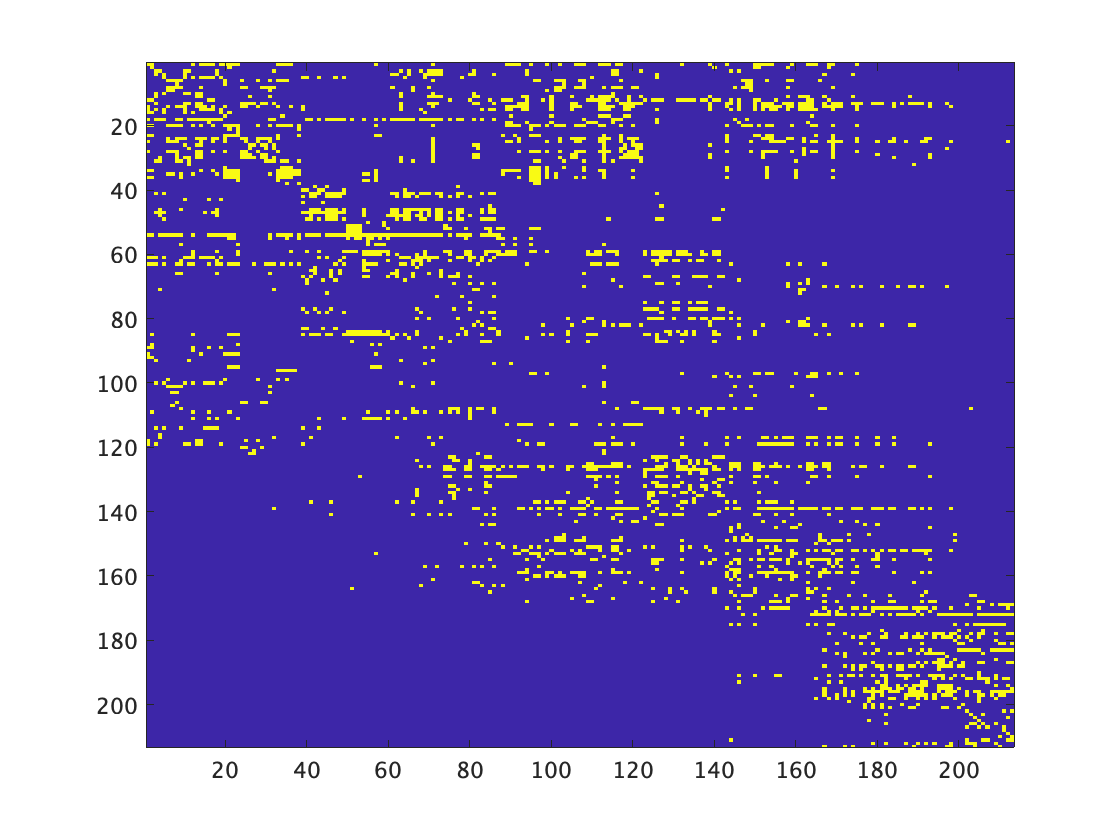

figure;
imagesc(connectionMatrixOhP005_sorted)

% make connectionIndexPairListOhP005_sorted
NConnection = sum(connectionMatrixOhP005_sorted,"all");
connectionIndexPairListOhP005_sorted = zeros(NConnection,2);
ctr = 1;
for ns = 1:NStructureOh
    for nt = 1:NStructureOh
        if connectionMatrixOhP005_sorted(ns,nt) == 1
            connectionIndexPairListOhP005_sorted(ctr,1) = ns;
            connectionIndexPairListOhP005_sorted(ctr,2) = nt;
            ctr = ctr + 1;
        end
    end
end

## Save Data

% /data/interim/Oh2014_Fulcher2016
save('structureInfoTableOh2014Sorted.mat','structureInfoTableOh2014Sorted')
save('expEnergyMatrixOh_nonMissing_normalizzed_sorted.mat','expEnergyMatrixOh_nonMissing_normalizzed_sorted')
save('connectionMatrixOhP005_sorted.mat','connectionMatrixOhP005_sorted')
save('connectionIndexPairListOhP005_sortedmat','connectionIndexPairListOhP005_sorted')
save('sortIndex.mat','sortIndex')
save('expEnergyMatrixOh_nonMissing_sorted.mat','expEnergyMatrixOh_nonMissing_sorted')